# Experiment 4: Transfer Learning with ResNet-50

## Clean environment

close all; clear variables; clc; rng(42);

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels, boundingBoxes] = ...
    loadDataset(folder, true);                                                    % :contentReference[oaicite:0]{index=0}​:contentReference[oaicite:1]{index=1}

Reading bounding box data


numClasses = height(classNames);

## Create datastores

trainingImageDS   = createImageDatastore(trainingImageNames,   folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  



validationImageDS = createImageDatastore(validationImageNames, folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  



testImageDS       = createImageDatastore(testImageNames,       folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  



## Load pretrained ResNet-50

net       = resnet50;                                                            % requires Deep Learning Toolbox Model for ResNet-50
inputSize = net.Layers(1).InputSize;                                             % [224 224 3]

## Resize & combine

targetSize = inputSize(1:2);
trainCDS = resizeCombineDatastore(trainingImageDS,   targetSize);
valCDS   = resizeCombineDatastore(validationImageDS, targetSize);
testCDS  = resizeCombineDatastore(testImageDS,       targetSize);

## Image preview

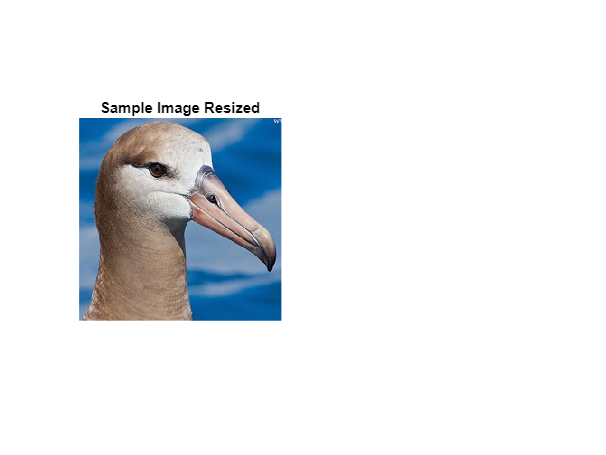

showImage(trainCDS)

## Enable GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7437021184 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Build the layer graph and swap out the last 3 layers

lgraph = layerGraph(net);

% 1) New fully‐connected layer (20 classes)
newFc = fullyConnectedLayer(numClasses, ...
    'Name','fc20', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);

% 2) New softmax
newSoftmax = softmaxLayer('Name','softmax20');

% 3) New classification output
newClassOutput = classificationLayer('Name','classoutput20');

% Replace them
lgraph = replaceLayer(lgraph, 'fc1000', newFc);
lgraph = replaceLayer(lgraph, 'fc1000_softmax', newSoftmax);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', newClassOutput);

## Training options

options = trainingOptions('adam', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',valCDS, ...
    'ValidationFrequency',floor(numel(trainingImageDS.Files)/32), ...
    'Verbose',true, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','gpu');

## Train

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        6.25% |       10.81% |       3.4270 |       3.1930 |      1.0000e-04 |
|       1 |          20 |       00:00:13 |       75.00% |       79.28% |       0.7008 |       0.6375 |      1.0000e-04 |
|       2 |          40 |       00:00:23 |       93.75% |       81.98% |       0.2998 |       0.5398 |      1.0000e-04 |
|       3 |          50 |       00:00:27 |      100.00% |              |       0.0177 |              |      1.0000

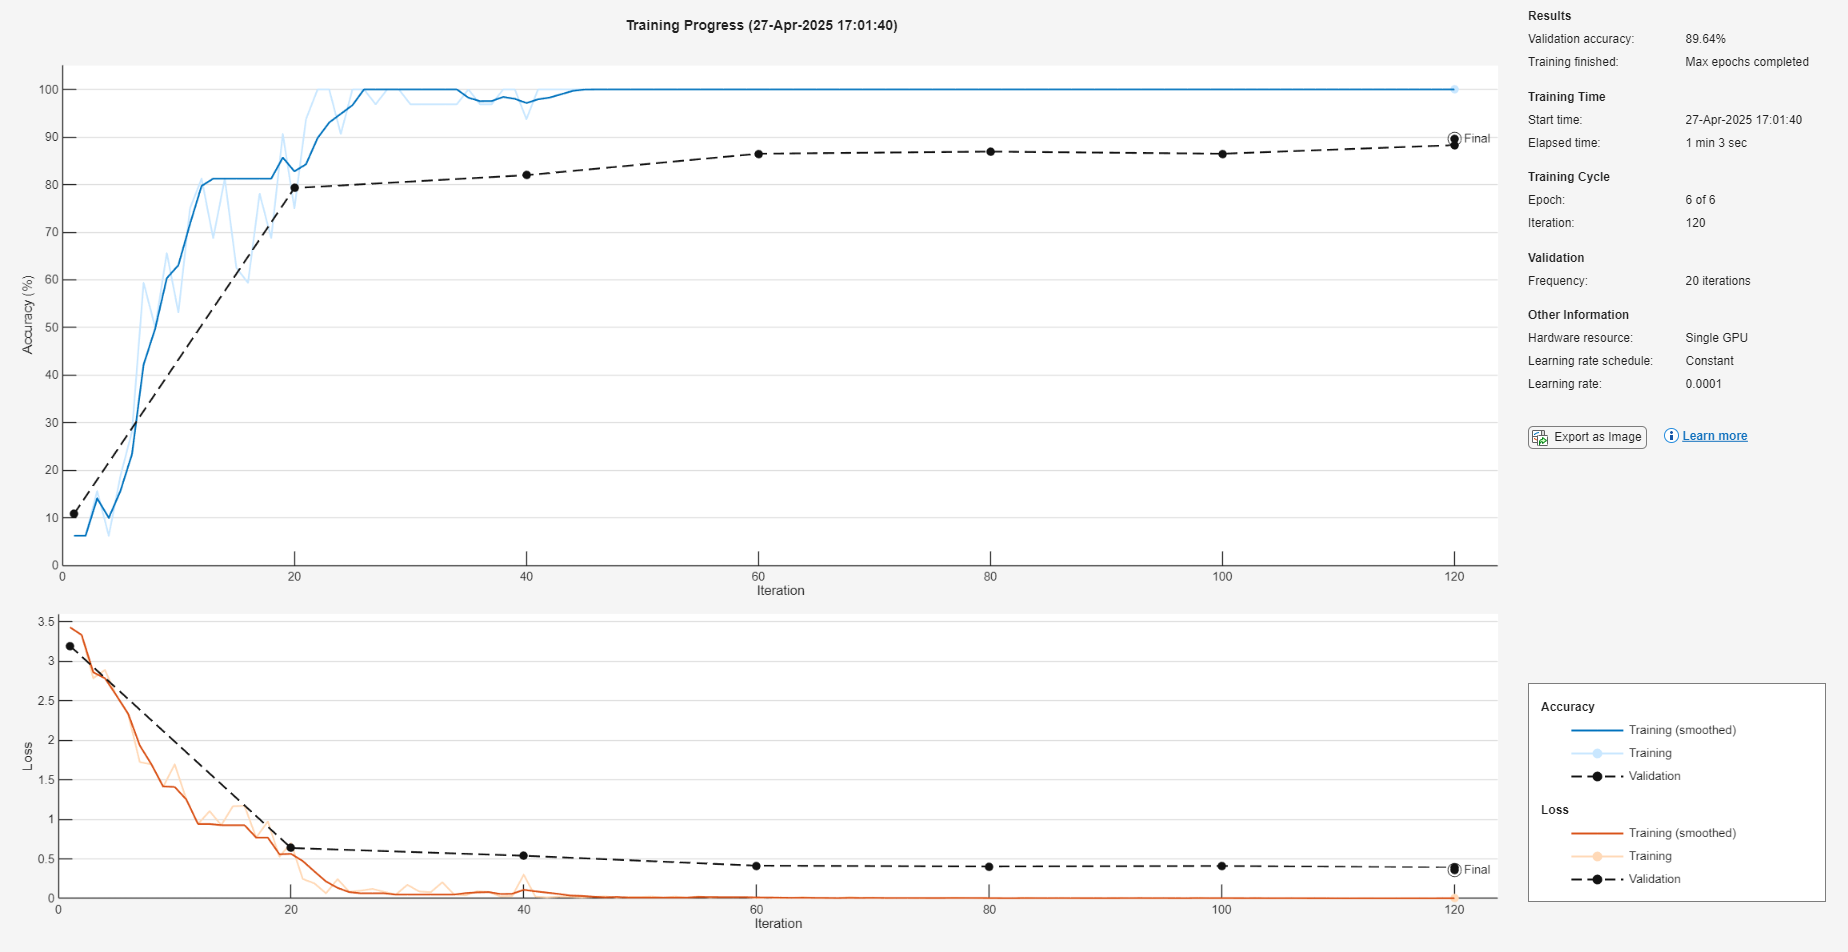

resnet20 = trainNetwork(trainCDS, lgraph, options);

## Evaluate

[trainAcc, ~]   = evaluateClassifier(resnet20, trainCDS,   trainingImageDS.Labels,   true);
[valAcc,   ~]   = evaluateClassifier(resnet20, valCDS,     validationImageDS.Labels, true);
[testAcc, preds] = evaluateClassifier(resnet20, testCDS,   testImageDS.Labels,       true);

fprintf("Train Accuracy = %.1f%%\n", trainAcc*100);

Train Accuracy = 100.0%


fprintf("Val   Accuracy = %.1f%%\n", valAcc*100);

Val   Accuracy = 89.6%


fprintf("Test  Accuracy = %.1f%%\n", testAcc*100);

Test  Accuracy = 92.8%


## Confusion matrix

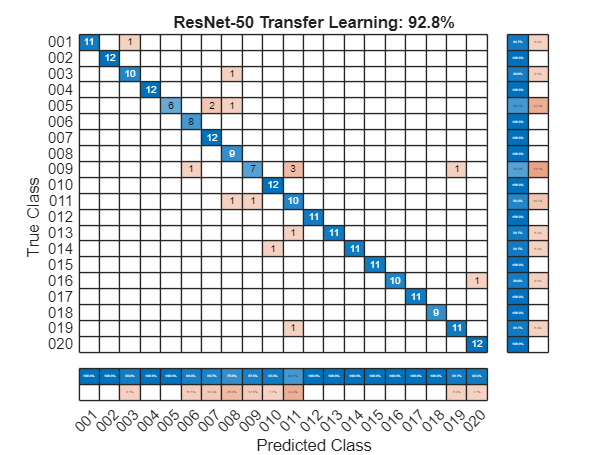

Classwise Recognition Rates:
   91.7000
  100.0000
   90.9000
  100.0000
   66.7000
  100.0000
  100.0000
  100.0000
   58.3000
  100.0000
   83.3000
  100.0000
   91.7000
   91.7000
  100.0000
   90.9000
  100.0000
  100.0000
   91.7000
  100.0000



plotConfusionMatrix(testImageDS.Labels, preds, ...
    sprintf("ResNet-50 Transfer Learning: %.1f%%", testAcc*100));





% %% Experiment 4: Transfer Learning with ResNet-50
% %% Clean environment
% 
% close all;
% clear variables;
% clc;
% rng(42);
% %% Set folder path
% 
% folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";
% %% Load dataset
% 
% [trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels, boundingBoxes] = loadDataset(folder, true);
% numClasses = height(classNames);
% %% Create datastores
% 
% disp('Training set class distribution:');
% trainingImageDS = createImageDatastore(trainingImageNames, folder, true, boundingBoxes);
% 
% disp('Validation set class distribution:');
% validationImageDS = createImageDatastore(validationImageNames, folder, true, boundingBoxes);
% 
% disp('Test set class distribution:');
% testImageDS = createImageDatastore(testImageNames, folder, true, boundingBoxes);
% %% Load pretrained ResNet-50
% 
% net = resnet50;                             % requires Deep Learning Toolbox Model for ResNet-50 Network
% inputSize = net.Layers(1).InputSize;        % typically [224 224 3]
% %% Resize image datastores and combine them with the labels
% 
% targetSize = inputSize(1:2);
% trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
% valCDS = resizeCombineDatastore(validationImageDS, targetSize);
% testCDS = resizeCombineDatastore(testImageDS, targetSize);
% %% Show images
% 
% showImage(trainCDS)
% %% Enables GPU
% 
% [device, useGPU] = enableGPU();
% %% CNN - Convolutional Neural Network
% %% Replace final layers to match numClasses
% 
% lgraph = layerGraph(net);
% %%
% lgraph.Layers
% %%
% %% Find the layers to replace
% [learnableLayer, classLayer] = findLayersToReplace(lgraph);
% 
% %% Create new layers
% newLearnableLayer = fullyConnectedLayer(numClasses, ...
%     'Name','new_fc', ...
%     'WeightLearnRateFactor',10, ...
%     'BiasLearnRateFactor',10);
% 
% newClassLayer = classificationLayer('Name','new_classoutput');
% 
% %% Replace the layers
% lgraph = replaceLayer(lgraph, learnableLayer.Name, newLearnableLayer);
% lgraph = replaceLayer(lgraph, classLayer.Name,     newClassLayer);
% %%
% 
% % % 1) Replace fully connected layer
% % newFCLayer = fullyConnectedLayer(numClasses, ...
% %     'Name','fc20', ...
% %     'WeightLearnRateFactor',10, ...
% %     'BiasLearnRateFactor',10);
% % lgraph = replaceLayer(lgraph, 'fc1000', newFCLayer);
% % 
% % % 2) Replace softmax
% % newSoftmax = softmaxLayer('Name','softmax20');
% % lgraph = replaceLayer(lgraph, 'fc1000_softmax', newSoftmax);
% % 
% % % 3) Replace classification output layer
% % newClassLayer = classificationLayer('Name','classoutput20');
% % lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', newClassLayer);
% %% Training options
% 
% options = trainingOptions('adam', ...
%     'MiniBatchSize',32, ...
%     'MaxEpochs',6, ...
%     'InitialLearnRate',1e-4, ...
%     'Shuffle','every-epoch', ...
%     'ValidationData',valCDS, ...
%     'ValidationFrequency',floor(numel(trainingImageDS.Files)/32), ...
%     'Verbose',true, ...
%     'Plots','training-progress', ...
%     'ExecutionEnvironment','gpu');          % uses GPU if available
% %% Train the network
% 
% resnet20 = trainNetwork(trainCDS, lgraph, options);
% %% Evaluate the model
% 
% [trainAcc, ~] = evaluateClassifier(resnet20, trainCDS,   trainingImageDS.Labels,   true);
% [valAcc,   ~] = evaluateClassifier(resnet20, valCDS,     validationImageDS.Labels, true);
% [testAcc,  preds] = evaluateClassifier(resnet20, testCDS, testImageDS.Labels,       true);
% 
% 
% fprintf("Train Accuracy = %.1f%%\n", trainAcc*100);
% fprintf("Val   Accuracy = %.1f%%\n", valAcc*100);
% fprintf("Test  Accuracy = %.1f%%\n", testAcc*100);
% %% Confusion matrix
% 
% plotConfusionMatrix(testImageDS.Labels, preds, ...
%     sprintf("ResNet-50 Transfer Learning: %.1f%%", testAcc*100));
% %% 
% %